# Figure 3D

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A010_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'siCtrl DMSO'         }    {[1 2 3 4]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCtrl DOX'          }    {[5 6 7 8]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCCNE/siCtrl DMSO'  }    {[1 2 3 4]}    {[3]}    {[1]}    {[0 0 0]}
    {'siCCNE/siCtrl DOX'   }    {[5 6 7 8]}    {[3]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCtrl DMSO'  }    {[1 2 3 4]}    {[4]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCtrl DOX'   }    {[5 6 7 8]}    {[4]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCCNA DMSO'  }    {[1 2 3 4]}    {[5]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCCNA DOX'   }    {[5 6 7 8]}    {[5]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCDC25a DMSO'}    {[1 2 3 4]}    {[6]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCDC25a DOX' }    {[5 6 7 8]}    {[6]}    {[1]}    {[0 0 0]}
    {'siCDC25a/siCCNA DMSO'}    {[1 2 3 4]}    {[7]}    {[1]}    {[0 0 0]}
    {'siCDC25a/siCCNA DOX' }    {[5 6 7 8]}    {[7]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCCNE DMSO'  }    {[1 2 3 4]}    {[8]}    {[1]}    {[0 0 


framesPerHr = 60/12;
frameDrugAdded = 13;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end


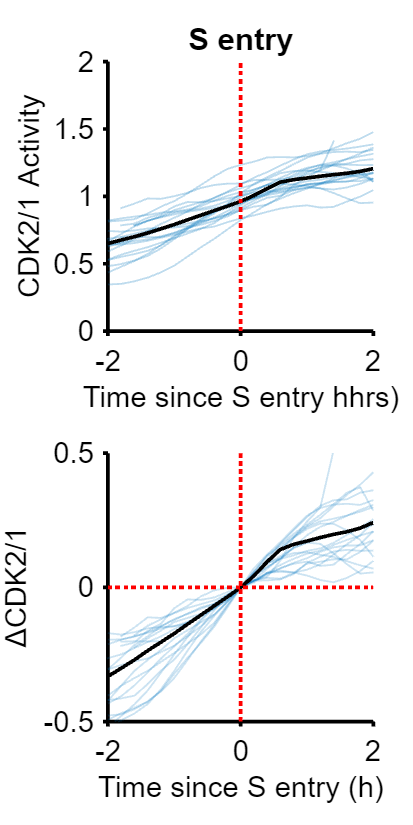

cellnum = 12126

cellnum = 1866

cellnum = 1743

cellnum = 5416

cellnum = 1961

cellnum = 214

cellnum = 9893

cellnum = 5976

cellnum = 6337

cellnum = 11282

cellnum = 9735

cellnum = 592

cellnum = 14451

cellnum = 11494

cellnum = 1101

cellnum = 5046

cellnum = 1185

cellnum = 6301

cellnum = 76

cellnum = 15209

rng(1)
cond =1;
poiAlign = [3];
xlimits = [-2 2];
names = {'S entry','APC off'};
f0 = figure('pos',[10 10 length(poiAlign)*300 600 ]);
% f1 = figure;
hold on

a = 1;
for i=1:length(poiAlign)
    figure(f0), hold on
    dat = S(cond);
    inds = ~isnan(dat.POI(:,poiAlign(i)))  & dat.apcExpressGate & dat.goodCdk   & (dat.POI_realtime(:,3)-dat.POI_realtime(:,1)) >3 ;%& dat.POI_realtime(:,1) < 20 ;
    
    
    cells = find(inds);
    
 
     slope = zeros(length(cells),1);
     cdkats=zeros(length(cells),1);

    cdkdata = dat.cdk(inds,:);
    cdkdata_zero = cdkdata;
    mitosis = dat.POI(inds,1);
    POI = dat.POI(inds,poiAlign(i));   
    
    for n = 1:size(cdkdata,1)
        cdkdata(n,1:mitosis(n)+8) = NaN;
        cdkdata_zero(n,:) = cdkdata(n,:) - cdkdata(n,POI(n));
    end
     [frames, cdk_mean, ~] =get_mean_trace(cdkdata,POI,1);
     [~, cdk_mean_zero, ~] =get_mean_trace(cdkdata_zero,POI,1); 


    for cellnum = randsample(cells,min([20 length(cells)]))'
         cellnum
        timeAligned = xTime+.2-dat.POI(cellnum,poiAlign(i))/framesPerHr;
        start = dat.POI(cellnum,1)+8;
        if dat.POI(cellnum,3)>10 & dat.POI(cellnum,3)<112-10
        sslope = dat.POI(cellnum,3)-10;
        sslopeend = dat.POI(cellnum,3)+10;
        smooth_cdk = nansmooth(dat.cdk(cellnum,:),7);

         coefficients = polyfit(smooth_cdk(sslope:sslopeend), xTime(sslope:sslopeend), 1);
slope(a) = coefficients(1);
cdkats(a) = smooth_cdk(1,dat.POI(cellnum,3));
a=a+1;



        end
f0;
        subplot(2,length(poiAlign),i),hold on
        patchline(timeAligned(start:end),smooth_cdk(start:end),...
            'edgecolor',lines(1),'linewidth',1,'edgealpha',0.25);

            plot(frames/framesPerHr,cdk_mean,'k','LineWidth',2)
        ylabel('CDK2/1 Activity');
        ylim([0 2]);
        xlim(xlimits);
        xlabel('Time since S entry hhrs)');
       title(names{i},'FontSize',17);
        vline(0)

% for slp = 1:numcell
% 
%       
% % Now get the slope, which is the first coefficient in the array:
% 
% 
% end 

        subplot(2,length(poiAlign),i+length(poiAlign)),hold on
        patchline(timeAligned(start:end),smooth_cdk(start:end) - smooth_cdk(dat.POI(cellnum,poiAlign(i))),...
            'edgecolor',lines(1),'linewidth',1,'edgealpha',0.2);
                    plot(frames/framesPerHr,cdk_mean_zero,'k','LineWidth',2)
        ylabel('\DeltaCDK2/1');
        xlabel('Time since S entry (h)');
        ylim([-.5 .5]);
        xlim(xlimits);
        hline(0)
        vline(0)
    end

% figure(f1), hold on
%     plot(frames/framesPerHr,cdk_mean_zero,'LineWidth',2)

end

%   figure
% histogram(slope,'normalization','probability','NumBins',20);
% figure
% scatter(slope,cdkats)

f0;
  print_pdf(['fig_3D.pdf'])